# Create Training Datastore

dataFolder = 'C:\Users\Ahhyun Yuh\Audio\Thingy52\combined'

dataFolder = 'C:\Users\Ahhyun Yuh\Audio\Thingy52\combined'


ads = audioDatastore(fullfile(dataFolder, 'train'), ...
    "IncludeSubfolders", true, ...
    "FileExtensions", '.wav', ...
    "LabelSource", 'foldernames')

ads =   audioDatastore - 속성 있음:

                       Files: {
                              ' ...\Audio\Thingy52\combined\train\0\210528-201308-317-322-0_0.wav';
                              ' ...\Audio\Thingy52\combined\train\0\210528-201308-317-322-0_1.wav';
                              ' ...\Audio\Thingy52\combined\train\0\210528-201308-317-322-0_2.wav'
                               ... and 11495 more
                              }
                     Folders: {
                              'C:\Users\Ahhyun Yuh\Audio\Thingy52\combined\train'
                              }
                      Labels: [0; 0; 0 ... and 11495 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


# Choose Class to Recognize

classes = categorical(["0", "1", "2", "3", "4", "5", "6", "7", "8", "9", "10"]);

isClass = ismember(ads.Labels, classes);
isUnknown = ~isClass;

includeFraction = 0.2;
mask = rand(numel(ads.Labels),1) < includeFraction;
isUnknown = isUnknown & mask;
ads.Labels(isUnknown) = categorical("unknown");

adsTrain = subset(ads,isClass|isUnknown);
countEachLabel(adsTrain)

ans = 11×2 table
    Label    Count
    _____    _____

     0        664 
     1       2423 
     10        82 
     2         97 
     3       4248 
     4        388 
     5        614 
     6        218 
     7        203 
     8       1653 
     9        908 


# Create Validation Datastore

ads = audioDatastore(fullfile(dataFolder, 'validation'), ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

ads =   audioDatastore - 속성 있음:

                       Files: {
                              ' ...\Audio\Thingy52\combined\validation\0\210528-222131-1-83-0_18.wav';
                              ' ...\Audio\Thingy52\combined\validation\0\210528-222131-1-83-0_2.wav';
                              ' ...\Audio\Thingy52\combined\validation\0\210528-222131-1-83-0_21.wav'
                               ... and 2872 more
                              }
                     Folders: {
                              'C:\Users\Ahhyun Yuh\Audio\Thingy52\combined\validation'
                              }
                      Labels: [0; 0; 0 ... and 2872 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"



isClass = ismember(ads.Labels, classes);
isUnknown = ~isClass;

includeFraction = 0.2;
mask = rand(numel(ads.Labels),1) < includeFraction;
isUnknown = isUnknown & mask;
ads.Labels(isUnknown) = categorical("unknown");

adsValidation = subset(ads,isClass|isUnknown);
countEachLabel(adsValidation)

ans = 11×2 table
    Label    Count
    _____    _____

     0        181 
     1        536 
     10        18 
     2         31 
     3       1078 
     4        105 
     5        172 
     6         61 
     7         52 
     8        417 
     9        224 


To train the network with the entire dataset and achieve the highest possible accuracy, set `reduceDataset` to `false`. To run this example quickly, set `reduceDataset` to `true`.

reduceDataset = false;
if reduceDataset
    numUniqueLabels = numel(unique(adsTrain.Labels));
    % Reduce the dataset by a factor of 20
    adsTrain = splitEachLabel(adsTrain,round(numel(adsTrain.Files) / numUniqueLabels / 20));
    adsValidation = splitEachLabel(adsValidation,round(numel(adsValidation.Files) / numUniqueLabels / 20));
end

# Extract Spectrograms from Audio

fs = 16000; % Known sample rate of the data set

segmentDuration = 1; % Duration of each speech clip (in seconds)
frameDuration = 0.025;
hopDuration = 0.010;

segmentSamples = round(segmentDuration*fs);
frameSamples = round(frameDuration*fs);
hopSamples = round(hopDuration*fs);
overlapSamples = frameSamples - hopSamples;

FFTLength = 512;
numBands = 128; % Number of mel filters in auditory spectrogram

afe = audioFeatureExtractor( ...
    'SampleRate',fs, ...
    'FFTLength',FFTLength, ...
    'Window',hann(frameSamples,'periodic'), ...
    'OverlapLength',overlapSamples, ...
    'melSpectrum',true)

afe =   audioFeatureExtractor - 속성 있음:

   Properties
                     Window: [400×1 double]
              OverlapLength: 240
                 SampleRate: 16000
                  FFTLength: 512
    SpectralDescriptorInput: 'linearSpectrum'

   Enabled Features
     melSpectrum

   Disabled Features
     linearSpectrum, barkSpectrum, erbSpectrum, mfcc, mfccDelta, mfccDeltaDelta
     gtcc, gtccDelta, gtccDeltaDelta, spectralCentroid, spectralCrest, spectralDecrease
     spectralEntropy, spectralFlatness, spectralFlux, spectralKurtosis, spectralRolloffPoint, spectralSkewness
     spectralSlope, spectralSpread, pitch, harmonicRatio


   To extract a feature, set the corresponding property to true.
   For example, obj.mfcc = true, adds mfcc to the list of enabled features.


setExtractorParams(afe,'melSpectrum','NumBands',numBands,'WindowNormalization',false)

Read a file from the dataset. Call extract to extract audio features. The output is a spectrum with time across rows.

x = read(adsTrain)

x =    -0.0023
   -0.0026
   -0.0028
   -0.0030
   -0.0029
   -0.0031
   -0.0031
   -0.0028
   -0.0027
   -0.0021


features = extract(afe, x)

features =          0    0.0027    0.0008    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.00

[numHops,numFeatures] = size(features)

numHops = 98

numFeatures = 128

# Extract Features and Apply logarithm to Melspectrogram

Determine the number of partitions for the dataset for Parallel Computing Toolbox. Use single partition if you do not have the toolbox.

if ~isempty(ver('parallel')) && ~reduceDataset
    pool = gcp;
    numPar = numpartitions(adsTrain,pool);
else
    numPar = 1;
end

For each partition, read from the datastore, and then extract the features.

parfor ii = 1:numPar
    subds = partition(adsTrain,numPar,ii);
    XTrain = zeros(numHops,numBands,1,numel(subds.Files));
    for idx = 1:numel(subds.Files)
        x = read(subds);
        XTrain(:,:,:,idx) = extract(afe,x);
    end
    XTrainC{ii} = XTrain;
end

Convert the output to a 4-dimensional array with auditory spectrograms along the fourth dimension.

XTrain = cat(4,XTrainC{:});

[numHops,numBands,numChannels,numSpec] = size(XTrain)

cale the features by the window power and then take the log. To obtain data with a smoother distribution, take the logarithm of the spectrograms using a small offset.

epsil = 1e-6;
XTrain = log10(XTrain + epsil);

Perform the feature extraction steps described above to the validation set.

if ~isempty(ver('parallel'))
    pool = gcp;
    numPar = numpartitions(adsValidation,pool);
else
    numPar = 1;
end
parfor ii = 1:numPar
    subds = partition(adsValidation,numPar,ii);
    XValidation = zeros(numHops,numBands,1,numel(subds.Files));
    for idx = 1:numel(subds.Files)
        x = read(subds);
        XValidation(:,:,:,idx) = extract(afe,x);
    end
    XValidationC{ii} = XValidation;
end
XValidation = cat(4,XValidationC{:});
XValidation = log10(XValidation + epsil);

Isolate the train and validation labels. Remove empty categories.

YTrain = removecats(adsTrain.Labels);
YValidation = removecats(adsValidation.Labels);

# Visualize Data

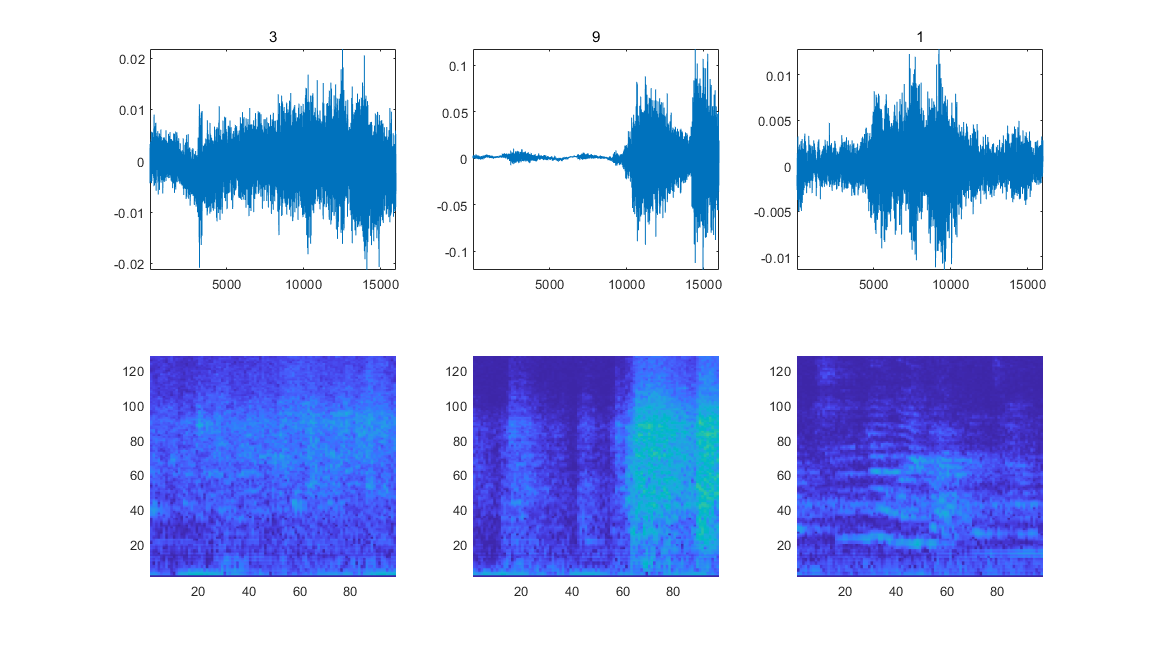

specMin = min(XTrain,[],'all');
specMax = max(XTrain,[],'all');
idx = randperm(numel(adsTrain.Files),3);
figure('Units','normalized','Position',[0.2 0.2 0.6 0.6]);
for i = 1:3
    [x,fs] = audioread(adsTrain.Files{idx(i)});
    subplot(2,3,i)
    plot(x)
    axis tight
    title(string(adsTrain.Labels(idx(i))))

    subplot(2,3,i+3)
    spect = (XTrain(:,:,1,idx(i))');
    pcolor(spect)
    caxis([specMin specMax])
    shading flat

    sound(x,fs)
    pause(2)
end

# Plot data distribution

Plot the distribution of the different class labels in the training and validation sets.

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5])

subplot(2,1,1)
histogram(YTrain)
title("Training Label Distribution")

subplot(2,1,2)
histogram(YValidation)
title("Validation Label Distribution")

# Define Neural Network Architecture

Conv2D Network Layer

numClasses = numel(categories(YTrain))

numClasses = 11

timePoolSize = ceil(numHops/8)

timePoolSize = 13

dropoutProb = 0.2;
numF = 12;

layers = [
    imageInputLayer([numHops numBands 1],"Name","imageinput")
    
    convolution2dLayer([3 3],numF,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same","Stride",[2 2])
    
    convolution2dLayer([3 3],2*numF,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([3 3],"Name","maxpool_2","Padding","same","Stride",[2 2])
    
    convolution2dLayer([3 3],4*numF,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([3 3],"Name","maxpool_3","Padding","same","Stride",[2 2])
    
    convolution2dLayer([3 3],4*numF,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    
    convolution2dLayer([3 3],4*numF,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    
    maxPooling2dLayer([timePoolSize 1],"Name","maxpool_4","Padding","same","Stride",[2 2])
    
    dropoutLayer(dropoutProb,"Name","dropout")
    fullyConnectedLayer(numClasses,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

# Train Network

miniBatchSize = 128;
validationFrequency = floor(numel(YTrain)/miniBatchSize);
options = trainingOptions('adam', ...
    'InitialLearnRate',3e-4, ...
    'MaxEpochs',25, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20);

Train the network. If you do not have a GPU, then training the network can take time.

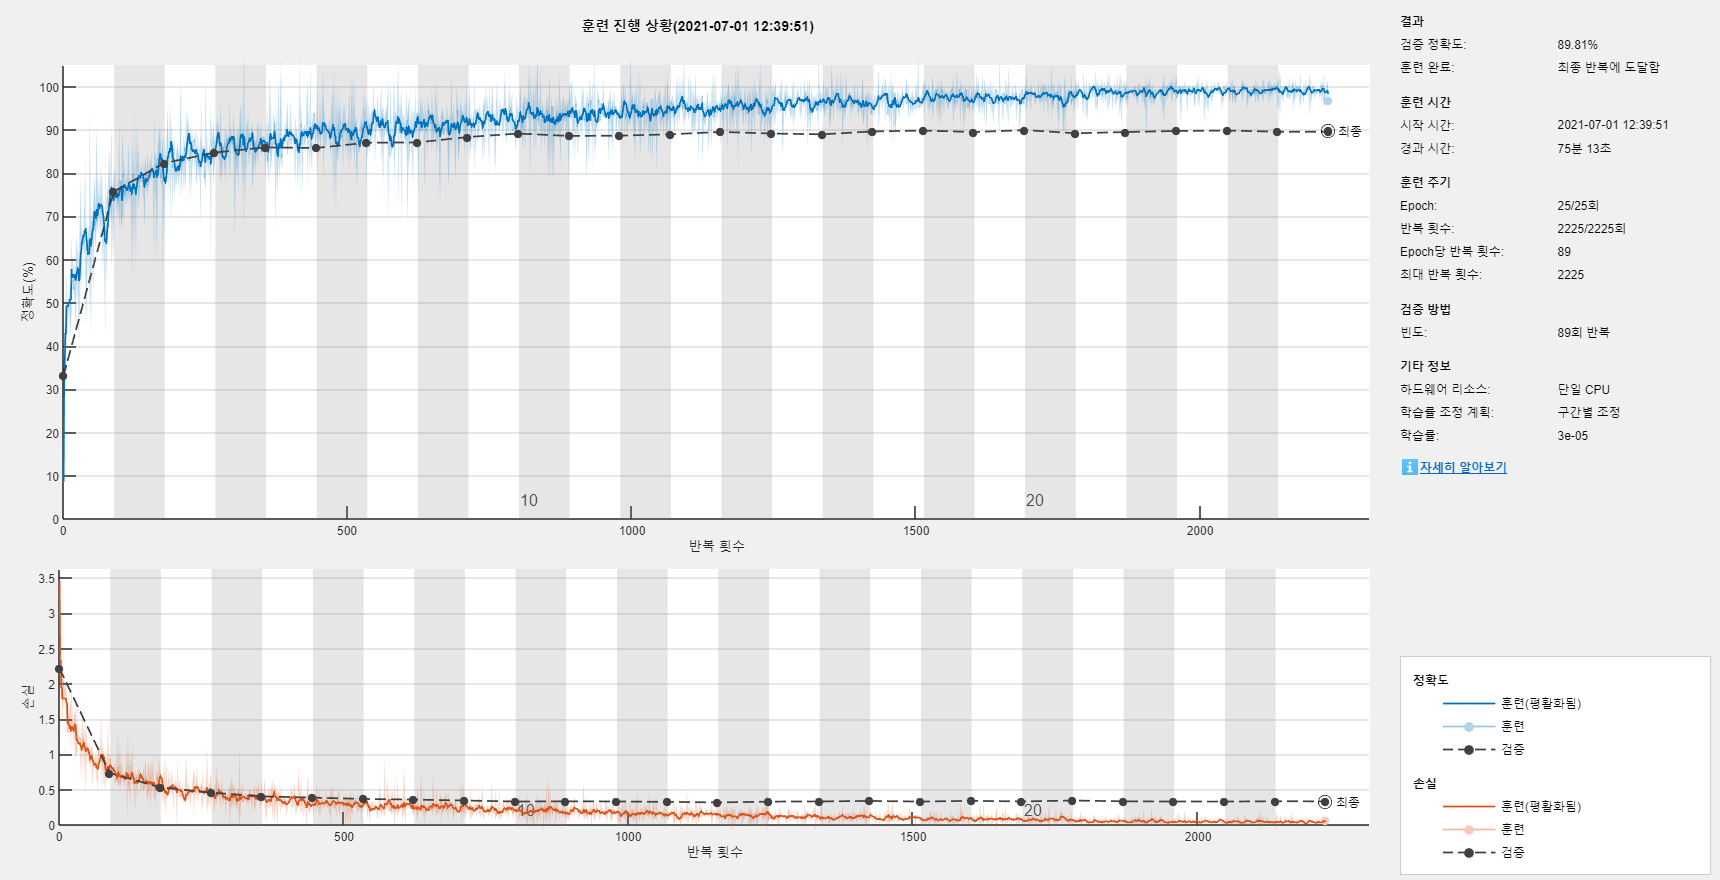

trainedNet = trainNetwork(XTrain,YTrain,layers,options);

Save trained network.

save('C:\Users\Ahhyun Yuh\Audio\Speech Command Recognition\trainedNet.mat','trainedNet')

# Evaluate Trained Network

YValPred = classify(trainedNet,XValidation);
validationError = mean(YValPred ~= YValidation);
YTrainPred = classify(trainedNet,XTrain);
trainError = mean(YTrainPred ~= YTrain);
disp("Training error: " + trainError*100 + "%")

Training error: 0.36528%


disp("Validation error: " + validationError*100 + "%")

Validation error: 10.1913%


# Plot Confusion Matrix

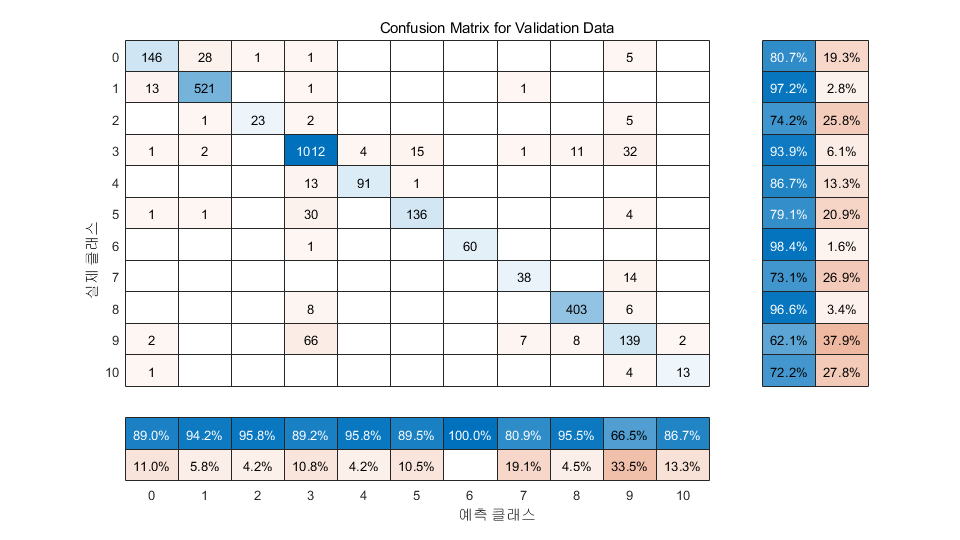

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
cm = confusionchart(YValidation,YValPred);
cm.Title = 'Confusion Matrix for Validation Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
sortClasses(cm, [classes])

# Network Performance

Compute the total size of the network in kilobytes and test its prediction speed when using a CPU.

info = whos('trainedNet');
disp("Network size: " + info.bytes/1024 + " kB")

Network size: 387.9434 kB



for i = 1:100
    x = randn([numHops,numBands]);
    tic
    [YPredicted,probs] = classify(trainedNet,x,"ExecutionEnvironment",'cpu');
    time(i) = toc;
end
disp("Single-image prediction time on CPU: " + mean(time(11:end))*1000 + " ms")

Single-image prediction time on CPU: 3.5779 ms
